BEO_st.name='BEO';
BEO_st.lat=42.1792;
BEO_st.lon=23.5856;
BEO_st.alt=2925;
BEO_st.env='Mt';
BEO_st.footp='Mx';


BEO_rd=read_betsy('BEO_2006_2018');

datevec(BEO_rd.Time(1))

ans =         2007           3          31           0           0           0


datevec(BEO_rd.Time(end))

ans =         2018           8          28           0           0           0


prctile(BEO_rd.U_S,[ 5 50 95])

ans =     4.0000   14.5500   25.6250


plotFigControl(BEO_rd, BEO_st.name);

Not enough input arguments.
Error in plotFigControl (line 20)
plotAllTS(station_datD,namesBs,CBs, STN);

%one size cut
% sc: a lot of holes, max in summer, no negatives
% abs: 2 size cut, max in summer, no negatives


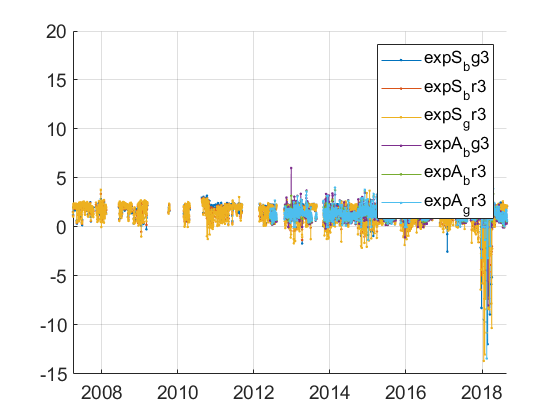

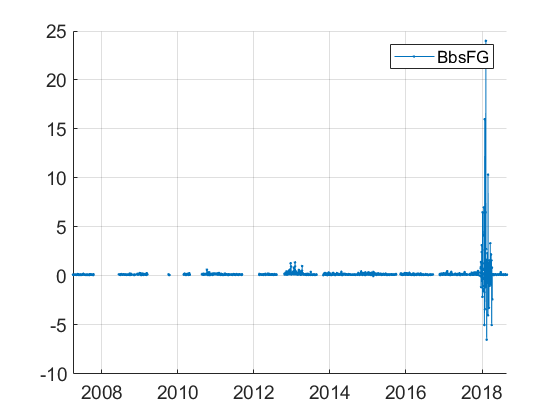

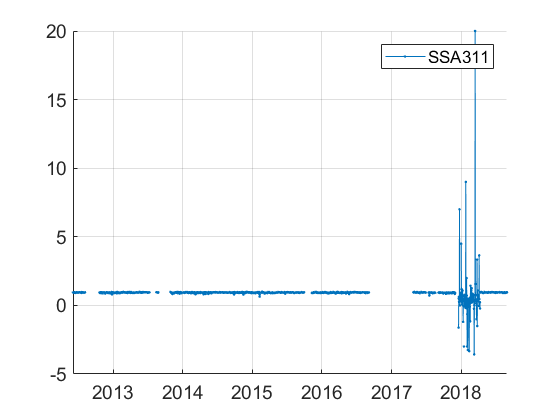

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
BEO_cal=compute_exp_SSA(BEO_rd,lambdaSC, lambdaAE);
plotFigControl_cal(BEO_cal, BEO_st.name);

%Questions:
%problems:
%sc:  seems too high in 2007
% sc strange: why is there always holes in October of almost each year ?
% SC begin 2018: about a factor of 100 too low + a lot of negatives + ratio between wavelength very noisy: why ?
%SC: something strange in the blue wavelenght (too high) in August-October 2010 ? ratio G/R also somewhat to high.
%SC ratio G/R: seems to be lower since November 2010 than before
%Bsp B/G ratio: seems too low and G/R too high from october to April 2013 --> G too high ??
% Bsp/sc much too high from october 2012 to April 2013
%sc exp: since october 2012 there is much more very low and negative data

%abs:middle 2013: too high ??
%abs: mid 2016-mid 2017: real hole or data lost in EBAS?

BEO_tr=BEO_rd;
BEO_tr.y=year(BEO_tr.Time);
% begin in March 2007 --> 2008 , yes not before there seems to be a rupture

%begin abs in 2013: too short for trend!
%end 2017
P=timerange('2008-01-01','2018-01-01');
BEO_tr=BEO_tr(P,:);
%RH ok- small change at the end of 2008 with lower RH thereafter: no need to compute the trend in RH and in dry
names=fieldnames(BEO_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"Ba";"G0_A";"R0_A"; "_dry";"SSA"; "expA"]);
N=names(c);
for i=1:length(N)
    BEO_tr.(N{i})=[];
end

%begin Bbs: 2009 (hole begin 2008. --> only 9 y
P2=timerange('2008-01-01','2009-01-01');
names=fieldnames(BEO_tr);
c= startsWith(names,'Bbs');
N=names(c);
for i=1:length(N)
    BEO_tr.(N{i})(P2)=NaN;
end

%sc and abs: invalidate 24 dec 2017-30 march 2018
p3=timerange('2017-12-24','2018-03-30');
c=startsWith(names,["Bbs";"Bs"]);
N=names(c);
for i=1:length(N)
    BEO_tr.(N{i})(p3)=NaN;
end
%abs: invalidate 10-24 August 2013
BEO_cal2=compute_exp_SSA(BEO_tr,lambdaSC, lambdaAE);
BEO_tr=outerjoin(BEO_tr, BEO_cal2);
% problem with larger variability of wavelength dependence: 17 Dec 2017-9
% April 2018: invalidate expS and SSA.

p3=timerange('2017-12-17','2018-04-09');
names=fieldnames(BEO_tr);
c=startsWith(names,'expS');
N=names(c);
for i=1:length(N)
    BEO_tr.(N{i})(p3)=NaN;
end

%compute trend only on G and expS_bg
BEO_tr.BsB_S=[];
    BEO_tr.BsR_S=[];
    BEO_tr.BbsB_S=[];
    BEO_tr.BbsR_S=[];
    
    BEO_tr.expS_br3=[];
     BEO_tr.expS_gr3=[];

BEO_result= all_trend_STN(BEO_tr,BEO_st); 

% all trends are ok
BEO_result_D=BEO_result;